[https://www.dsprelated.com/freebooks/filters/Analysis_Digital_Comb_Filter.html](https://www.dsprelated.com/freebooks/filters/Analysis_Digital_Comb_Filter.html)

Comb Filter analysis.  The difference equation


$$y(n) = x(n) + g_1x(n-M_1)-g_2y(n-M_2)$$


### Impulse response

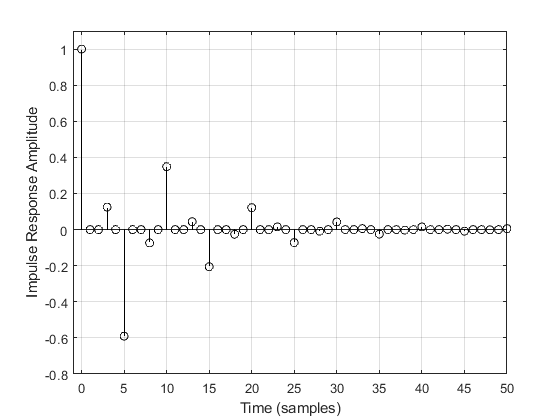

g1 = (0.5)^3;        % Some specific coefficients
g2 = (0.9)^5;
B = [1 0 0 g1];      % Feedforward coefficients, M1=3
A = [1 0 0 0 0 g2];  % Feedback coefficients, M2=5

x = [1,zeros(1,50)];       % Random test input signal
h = filter(B,A,x);   % Matlab and Octave compatible 


% Matlab-compatible plot:
clf; figure(1); stem([0:50],h,'-k'); axis([0 50 -0.8 1.1]);
ylabel('Impulse Response Amplitude'); xlabel('Time (samples)'); grid;
xlim([-1,50])

### Transfer Function


$$Z(Y(n)) = Z(x(n)) + g1Z(x(n-M_1) - g2Z(y(n-M_2)$$



$$Y(z) + g2z^{-M_2}Y(z) = X(z)+g1z^{-M_1}X(z)$$



$$H(z) \triangleq \frac{Y(z)}{X(z)} = \frac{1+g1z^{M_1}}{1+g2z^{M_2}$$


### Frequency and Phase Response


$$|H(e^{jwt}|=|\frac{1+g_1e^-jM_1wT}{1+g_2e^-jM_2wT}$$


so for the example:

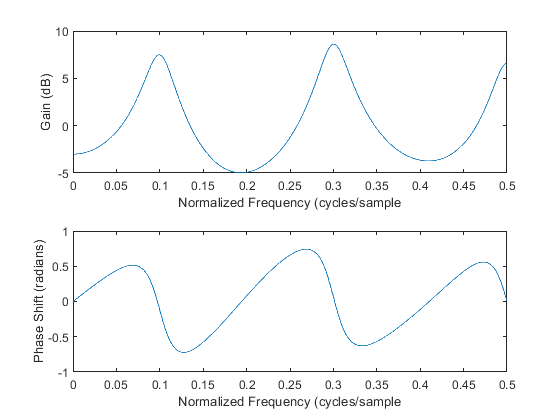

n = 1024;
[h,w] = freqz(B,A,n);
f = w/(2*pi);
figure(2)
subplot(2,1,1)
plot(f,20*log10(abs(h)))
xlabel('Normalized Frequency (cycles/sample')
ylabel('Gain (dB)')
subplot(2,1,2)
plot(f,angle(h))
xlabel('Normalized Frequency (cycles/sample')
ylabel('Phase Shift (radians)')

### Pole=Zero Analysis

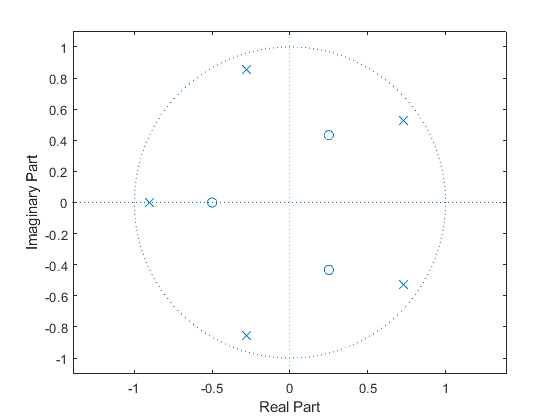

clf; figure(3)
[q,p,gain]=tf2zp(B,A);
zplane(q,p)

disp(p), 

  -0.9000 + 0.0000i
  -0.2781 + 0.8560i
  -0.2781 - 0.8560i
   0.7281 + 0.5290i
   0.7281 - 0.5290i



disp(q)

  -0.5000 + 0.0000i
   0.2500 + 0.4330i
   0.2500 - 0.4330i



Using the 5 poles and 3 zeros, we can expand the transfer function into a sum of five first order terms using partial fraction expansion.